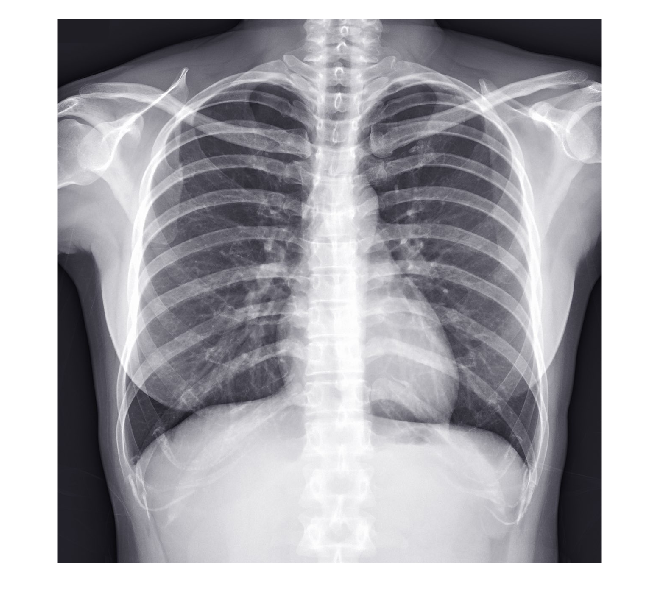

f = imread('radiograph1.jpg'); % leer imagen en archivos
imshow(f); % muestra imagen

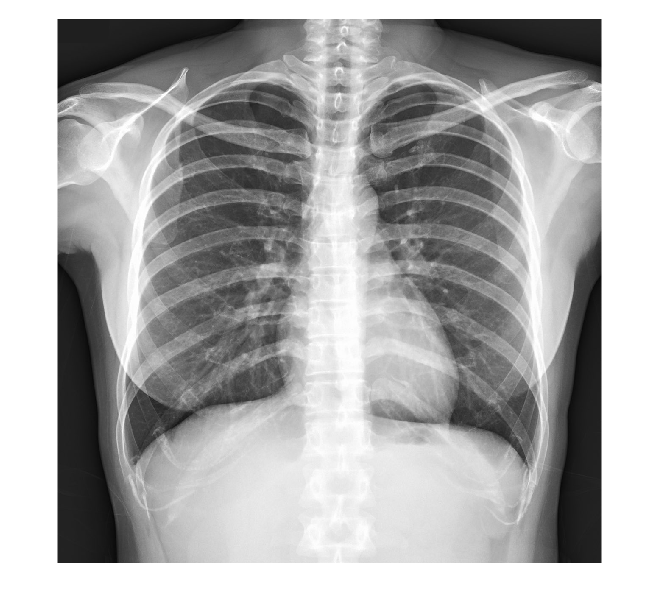

f = f(:,:,1); % escala los datos de RGB a una escala de 0 a 1
imshow(f);

f = double(f)/255; % convertir a dobles para evitar redondeos y usar numeros reales
imshow(f);

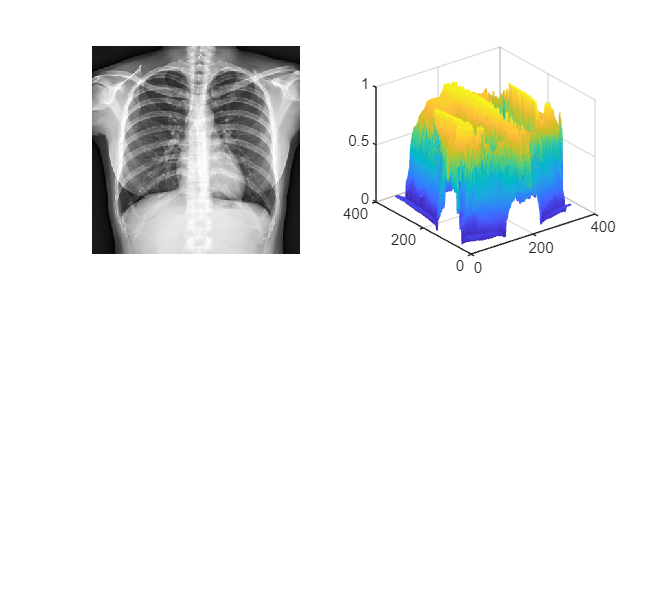

f = imresize(f,0.25); % muestreo para reducir tamaño de al imagen 1:4

figure(1);
subplot(2,2,1);
imshow(f,[]); % corchetes hacen que sea el valor max o min
subplot(2,2,2);
mesh(f) % genera un mapa topográfico para visualizar alturas

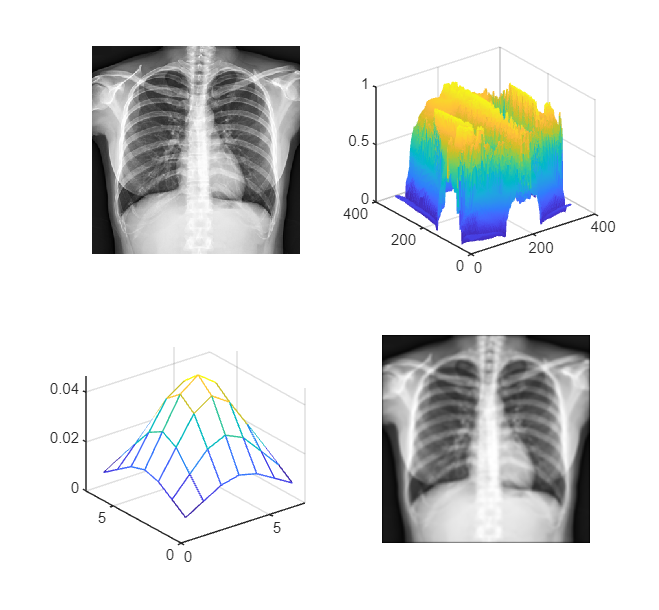

% h = 10*fspecial('disk',10); % hace borrosa la imagen, representación de la distorsión
h = fspecial('gaussian',7,2);


subplot(2,2,3);
% imshow(h,[]);
mesh(h)

sum(sum(h)); % tiene que ser igual a 1

g = conv2(f,h,"same"); % operacion de convolucion  

subplot(2,2,4);
imshow(g,[]);

% mesh(g)
% psf -> proviene de fenomenos fisicos, luz y distancia

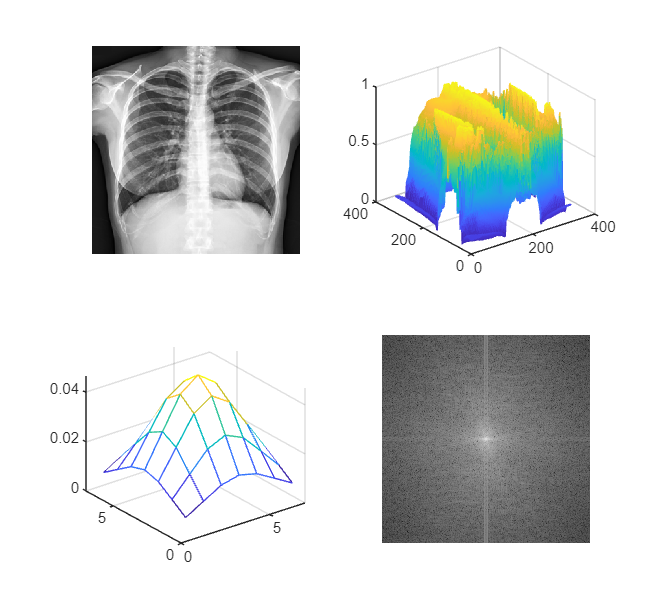

F = fft2(f,sz(1),sz(2)); 

subplot(2,2,4);
imshow(fftshift(log(abs(F))), []);

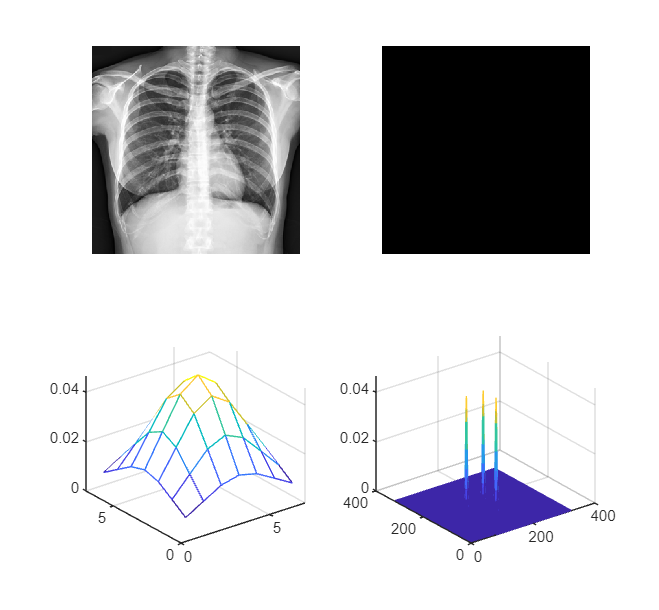

sz = size(f);

f = zeros(sz(1)); % matriz de zeros
% puntos de distorcion
f(int16(sz(1)/2),int16(sz(2)/2)) = 1;
f(int16(sz(1)/3),int16(sz(2)/2)) = 1;
f(int16(sz(1)/2),int16(sz(2)/3)) = 1;
subplot(2,2,2);
imshow(f,[]);

h = fspecial('gaussian',7,2); % representacion gaussiana
subplot(2,2,3);
mesh(h)
g = conv2(f,h,"same"); % output psf
% punto de estímulo indica psf de imagen, función de distorsión
subplot(2,2,4);
imshow(g,[]);
mesh(g)

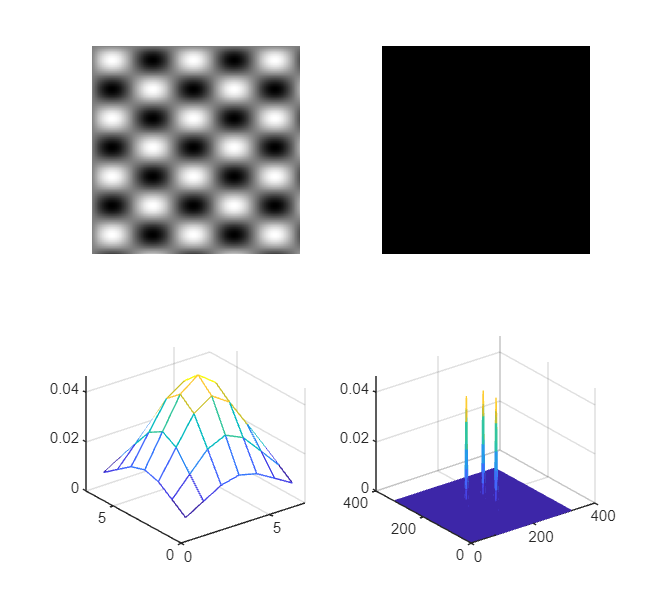

% y,x porque los indices están volteados
for (x = 1:sz(1))
    for (y = 1:sz(2))
        f(y,x) = sin(y*0.07) * sin(x*0.05); % define la orientación, representa frecuencia
    end
end
subplot(2,2,1);
imshow(f,[]);

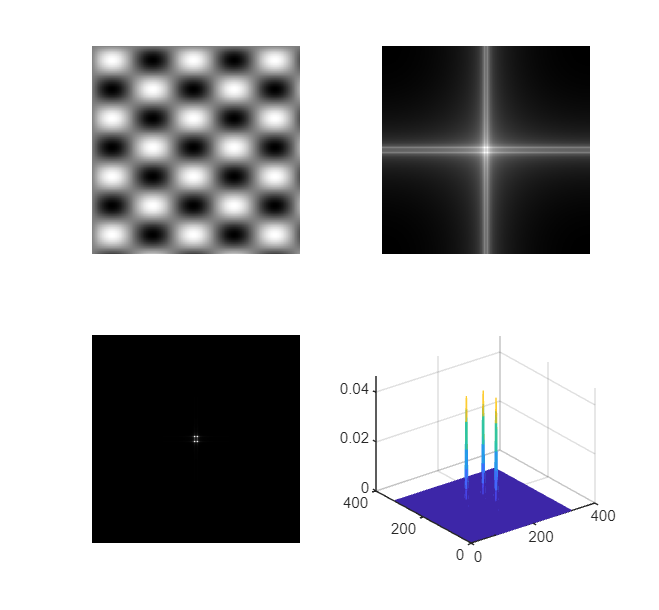

F = fft2(f,sz(1),sz(2));

subplot(2,2,2);
imshow(fftshift(log(abs(F))),[]); % dibuja puntos y líneas

subplot(2,2,3);
imshow(fftshift((abs(F))),[]); % dibuja puntos


% Fourier frecuencias positivas o negativas, buscamos el pico, separación indica la frecuencia 
% (alta frecuencia - separación amplia, baja frecuencia - separación estrecha) 

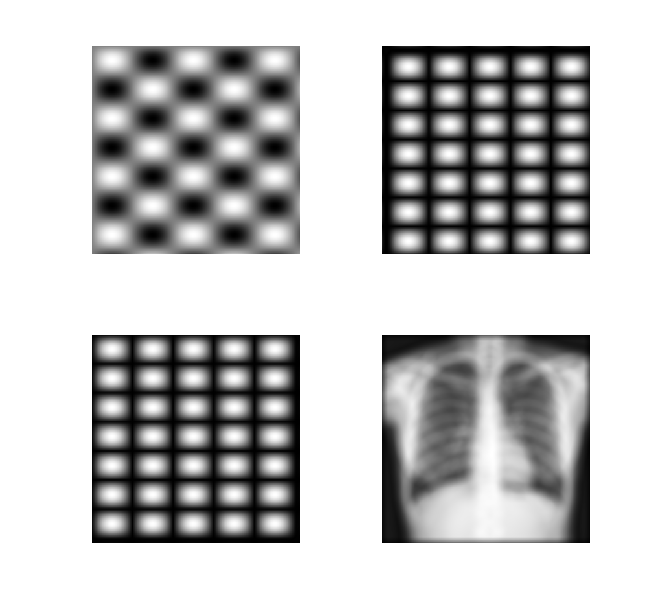

f = imread('radiograph1.jpg');

imshow(f);
f = f(:,:,1);
imshow(f);
f = double(f)/255;
imshow(f);
f=imresize(f,0.25);

h = fspecial('disk',10);
H=fft2(h,sz(1),sz(2));
G = F.*H;
g = abs(ifft2(G));

subplot(2,2,2);
imshow(g,[]);

G = F.*abs(H);
g = abs(ifft2(G));
subplot(2,2,3);
imshow(g,[]);
g2 = conv2(f,h,'same');

subplot(2,2,4);
imshow(g2,[]);